# Expand Example 3.43:

This live script is for use with the textbook

*Continuous-Time Signals and Systems: A MATLAB Integrated Approach*

by Oktay Alkin, CRC Press, 2025.

The system function for the first-order RC circuit is

        
$$H(f)=\frac{1}{1+j\omega RC}$$


Let

        
$$\omega_{c}=\frac{1}{RC}=2\pi f_{c}$$


and the system function can be written in the form

        
$$H(f)=\frac{1}{1+j(f/f_{c})$$


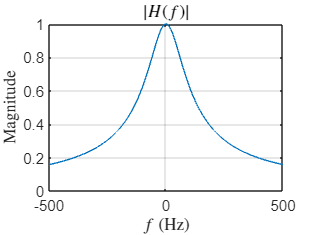

fc = 80; % 3-dB cutoff frequency
%
f = [-500:0.1:500];     % Vector of frequency values
H = 1./(1+j*f/fc);      % Evaluate the system function
% Graph the magnitude and the phase of the system function
plot(f,abs(H)); grid;
set(0,'defaultTextInterpreter','latex');
xlabel('$f$ (Hz)');
ylabel('Magnitude');
title('$|H(f)|$');

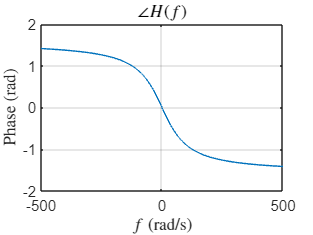

plot(f,angle(H)); grid;
xlabel('$f$ (rad/s)');
ylabel('Phase (rad)');
title('$\angle H(f)$');

set(0,'defaultTextInterpreter','tex');